# **GPS Simulink Model**

#### (Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester).

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

#### Under Supervision of:

-  Prof. Dr. Mohamed Ibrahim Awad (Mechatronics Head Faculty of Engineering - Ain Shams University).

%Open GPS Simulink Model
GPSModelPath = 'D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\gps\GPSModel';  %Change the path according to the model path in your device 
open_system(GPSModelPath);

%Load vechile path 
dataT = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesT.mat');
dataX = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesX.mat');
dataY = load('D:\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\Getting_Familiar_withToolboxes\threeVehiclesScene\refPosesY.mat');

%Get the data of X, Y and Yaw
refPosesT = dataT.refPosesT;
refPosesX = dataX.refPosesX;
refPosesY = dataY.refPosesY;

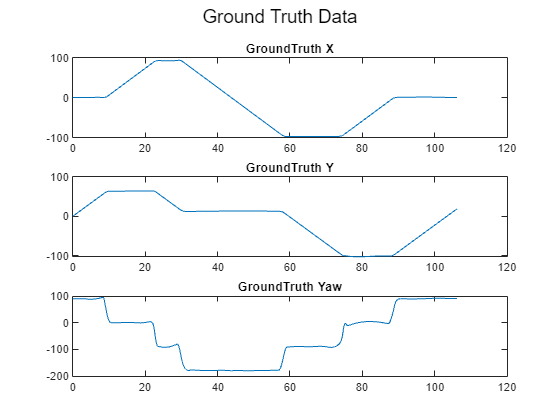

%Visualize groundtruth X, Y, and Yaw data.
timeVector = refPosesX(:,1); %Which is also consists of 500 element with deltaT = 0.21245(sec.)
refX = refPosesX(:,2)+17.5109; %Plot X data starting from X(0) = 0
refY = refPosesY(:,2)+11.1966; %Plot Y data starting from Y(0) = 0
refYaw = refPosesT(:,2); %Plot Yaw data starting from Yaw(0) = 0
figure;

%Creating subplots
subplot(3, 1, 1);
plot(timeVector, refX);
title('GroundTruth X');
 
 
subplot(3, 1, 2);
plot(timeVector, refY);
title('GroundTruth Y');
 
 
subplot(3, 1, 3);
plot(timeVector, (refYaw));
title('GroundTruth Yaw');
sgtitle('Ground Truth Data'); 

%Velocity calculations 
%Calculating the velocity using differentiation
dt = diff(timeVector); 
ddX = diff(refX); 
ddY = diff(refY);

Vx = [ddX(1) ./ dt(1); ddX ./ dt]; %Velocity in X_direction
timeVelocityMatrixX = [timeVector, Vx];
Vy = [ddY(1) ./ dt(1); ddY ./ dt]; %Velocity in Y_direction
timeVelocityMatrixY = [timeVector, Vy];
Vz = (sqrt(Vx.^2 + Vy.^2)); %Velocity in Z_direction
timeVelocityMatrixZ = [timeVector, Vz];

%Run Simulink Model
sim(GPSModelPath);

GPSn = zeros(500, 1);
GPSe = zeros(500, 1);

%Reshape LLA GPS data 
LLA_data = reshape(out.LLA.Data, [3, 500]);

for i = 1:500
    %Convert LLA coordinates to XYZ coordinates
    [deltaE, deltaN, ~] = lla_to_enu(LLA_data(2, 1), LLA_data(1, 1), LLA_data(3, 1), LLA_data(2, i), LLA_data(1, i), LLA_data(3, i));
    GPSe(i) = deltaE;
    GPSn(i) = deltaN;
end

yaw = (out.Course.Data);
%yawN = zeros(500, 1);
%Reshape yaw 
yaw = reshape(yaw, [], 1);
%Convert course angles range from 0 to 360 to include -ve angles also
GPSYaw = yaw - 360 * floor(yaw / 360 + 0.5);
for i =1:500
    if GPSYaw(i) > 135
        GPSYaw(i) = -180 - (180 - GPSYaw(i));
    end
end 

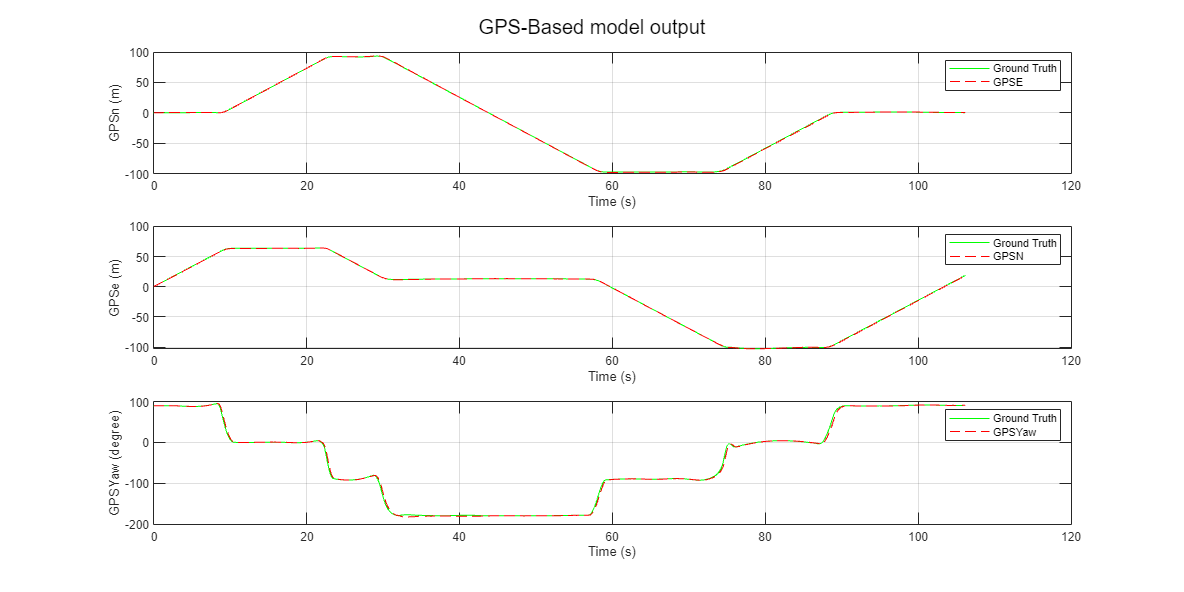

%Plot ground truth vs. GPS estimation
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, refX, 'g');
hold on;
plot(timeVector, GPSe, 'r--');
xlabel('Time (s)');
ylabel('GPSn (m)');
legend('Ground Truth', 'GPSE');
grid on;

subplot(3, 1, 2);
plot(timeVector, refY, 'g');
hold on;
plot(timeVector, GPSn, 'r--');
xlabel('Time (s)');
ylabel('GPSe (m)');
legend('Ground Truth', 'GPSN');
grid on;

subplot(3, 1, 3);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, GPSYaw, 'r--');
xlabel('Time (s)');
ylabel('GPSYaw (degree)');
legend('Ground Truth', 'GPSYaw');
grid on;
sgtitle('GPS-Based model output');

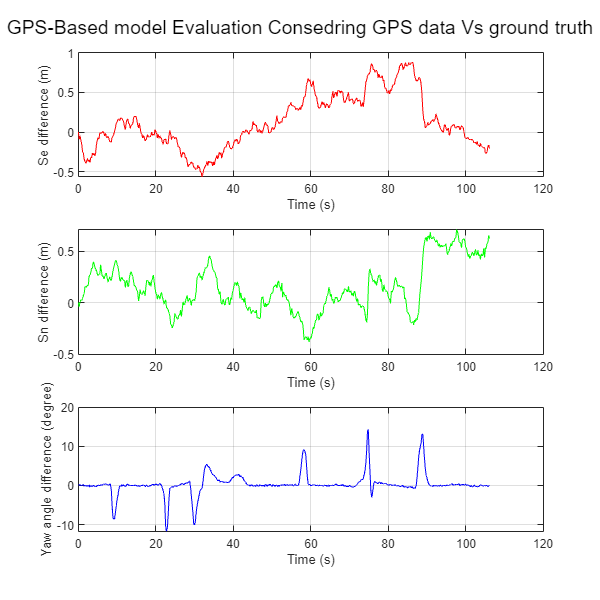

%Calculating Error between GPS and ground truth
XDiffGPS = refX - GPSe;
YDiffGPS = refY - GPSn;
YawDiffGPS = refYaw - GPSYaw;

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); %left bottom width height

subplot(3, 1, 1);
plot(timeVector, XDiffGPS, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, YDiffGPS, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, YawDiffGPS, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (degree)');
grid on;

sgtitle('GPS-Based model Evaluation Consedring GPS data Vs ground truth');